#### Name : Ghosh Kushanava Amitava

#### Roll No : 220123083

#### Course : MA 423

format long e

Q.1  To illustrate anomaly in automatic computation.

(4/3 - 1)*3 - 1

ans = -2.2204e-16

5 * ((1 + exp(-50)) - 1)/((1 + exp(-50)) - 1)

ans = NaN

log(exp(750))/100

ans = Inf

Conclusion: 

1. The anomaly is due to **roundoff error** and **cancellation**.

2. The anomaly is due to **underflow** and **loss of significance**.

3. The anomaly is due to **overflow**.

Q.2  Try to approximate the values of each of the functions

f = @(x) (tan(x) - x)./(x.^3);
g = @(x) (exp(x) + cos(x) - sin(x) - 2)./(x.^3);
h = @(x) (exp(x) - 1)./x;

(b)

F = @(x) (1/3 + (2/15)*x.^2);
G = @(x) (1/3 + x/6);
H = @(x) (1 + x/2 + (x.^2)/6);

(a)

p = 1:16;
x = 10.^(-p);
f_lim = 1/3;
g_lim = 1/3;
h_lim = 1;
f_exact = f(x)

f_exact =      3.346720854505436e-01     3.333466672070239e-01     3.333334667315890e-01     3.333333365189081e-01     3.333328757329849e-01     3.333074647445672e-01     3.308722450212111e-01                         0                         0                         0                         0                         0                         0                         0                         0                         0


g_exact = g(x)

g_exact =      3.416667068454337e-01     3.341666667822096e-01     3.334168496849088e-01     3.335109965973970e-01     4.440892098500628e-01                         0    -2.220446049250313e+05                         0                         0                         0                         0                         0                         0    -2.220446049250313e+26    -2.220446049250313e+29                         0


h_exact = h(x)

h_exact =      1.051709180756477e+00     1.005016708416795e+00     1.000500166708385e+00     1.000050001667141e+00     1.000005000006965e+00     1.000000499962184e+00     1.000000049433680e+00     9.999999939225290e-01     1.000000082740371e+00     1.000000082740371e+00     1.000000082740371e+00     1.000088900582341e+00     9.992007221626409e-01     9.992007221626409e-01     1.110223024625157e+00                         0


f_approx = F(x)

f_approx =      3.346666666666667e-01     3.333466666666666e-01     3.333334666666666e-01     3.333333346666666e-01     3.333333333466666e-01     3.333333333334667e-01     3.333333333333346e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01


g_approx = G(x)

g_approx =      3.500000000000000e-01     3.350000000000000e-01     3.335000000000000e-01     3.333500000000000e-01     3.333350000000000e-01     3.333335000000000e-01     3.333333500000000e-01     3.333333350000000e-01     3.333333335000000e-01     3.333333333500000e-01     3.333333333350000e-01     3.333333333335000e-01     3.333333333333500e-01     3.333333333333350e-01     3.333333333333335e-01     3.333333333333333e-01


h_approx = H(x)

h_approx =      1.051666666666667e+00     1.005016666666667e+00     1.000500166666667e+00     1.000050001666667e+00     1.000005000016667e+00     1.000000500000167e+00     1.000000050000002e+00     1.000000005000000e+00     1.000000000500000e+00     1.000000000050000e+00     1.000000000005000e+00     1.000000000000500e+00     1.000000000000050e+00     1.000000000000005e+00     1.000000000000000e+00     1.000000000000000e+00


err_f = abs(f_exact - f_lim)

err_f =      1.338752117210240e-03     1.333387369062411e-05     1.333982557194524e-07     3.185574748432174e-09     4.576003483913738e-07     2.586858876607590e-05     2.461088312122217e-03     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01


err_F = abs(f_approx - f_lim)

err_F =      1.333333333333353e-03     1.333333333330966e-05     1.333333333186637e-07     1.333333332631526e-09     1.333333443653828e-11     1.333377852574813e-13     1.332267629550188e-15                         0                         0                         0                         0                         0                         0                         0                         0                         0


err_g = abs(g_exact - g_lim)

err_g =      8.333373512100395e-03     8.333334488762612e-04     8.351635157549664e-05     1.776632640636544e-04     1.107558765167295e-01     3.333333333333333e-01     2.220449382583647e+05     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     3.333333333333333e-01     2.220446049250313e+26     2.220446049250313e+29     3.333333333333333e-01


err_G = abs(g_approx - g_lim)

err_G =      1.666666666666666e-02     1.666666666666650e-03     1.666666666666483e-04     1.666666666666483e-05     1.666666666677585e-06     1.666666666899630e-07     1.666666665789407e-08     1.666666693544983e-09     1.666666804567285e-10     1.666666804567285e-11     1.666666804567285e-12     1.666444759962360e-13     1.665334536937735e-14     1.665334536937735e-15     1.665334536937735e-16                         0


err_h = abs(h_exact - h_lim)

err_h =      5.170918075647712e-02     5.016708416794913e-03     5.001667083845973e-04     5.000166714097531e-05     5.000006964905879e-06     4.999621836532242e-07     4.943368026033568e-08     6.077470970922150e-09     8.274037099909037e-08     8.274037099909037e-08     8.274037099909037e-08     8.890058234101161e-05     7.992778373591136e-04     7.992778373591136e-04     1.102230246251565e-01     1.000000000000000e+00


err_H = abs(h_approx - h_lim)

err_H =      5.166666666666675e-02     5.016666666666669e-03     5.001666666666349e-04     5.000166666668804e-05     5.000016666700802e-06     5.000001668253873e-07     5.000000169452790e-08     4.999999969612645e-09     5.000000413701855e-10     5.000000413701855e-11     5.000000413701855e-12     5.000444502911705e-13     4.996003610813204e-14     5.107025913275720e-15     4.440892098500626e-16                         0


(c)

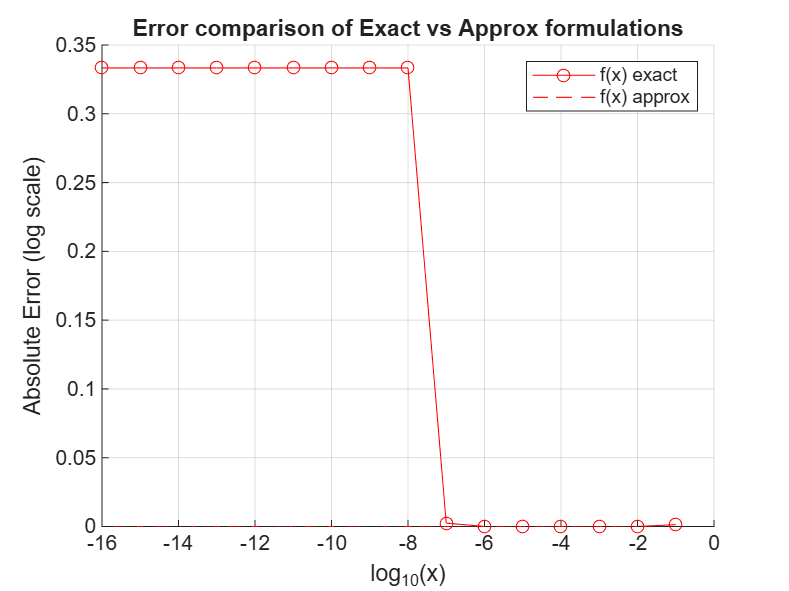

figure;
hold on;
semilogy(log10(x), err_f, 'r-o', 'DisplayName','f(x) exact');
semilogy(log10(x), err_F, 'r--', 'DisplayName','f(x) approx');
xlabel('log_{10}(x)');
ylabel('Absolute Error (log scale)');
legend show;
title('Error comparison of Exact vs Approx formulations');
grid on;

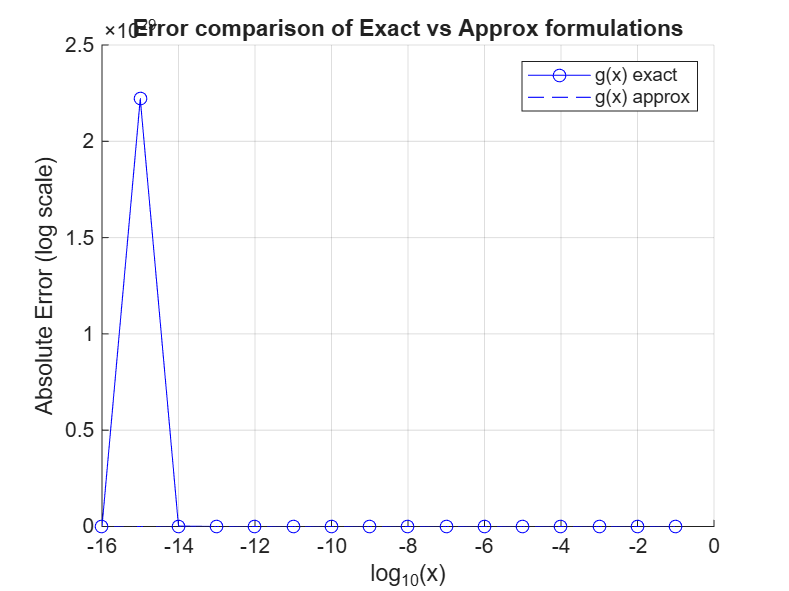

figure;
hold on;
semilogy(log10(x), err_g, 'b-o', 'DisplayName','g(x) exact');
semilogy(log10(x), err_G, 'b--', 'DisplayName','g(x) approx');
xlabel('log_{10}(x)');
ylabel('Absolute Error (log scale)');
legend show;
title('Error comparison of Exact vs Approx formulations');
grid on;

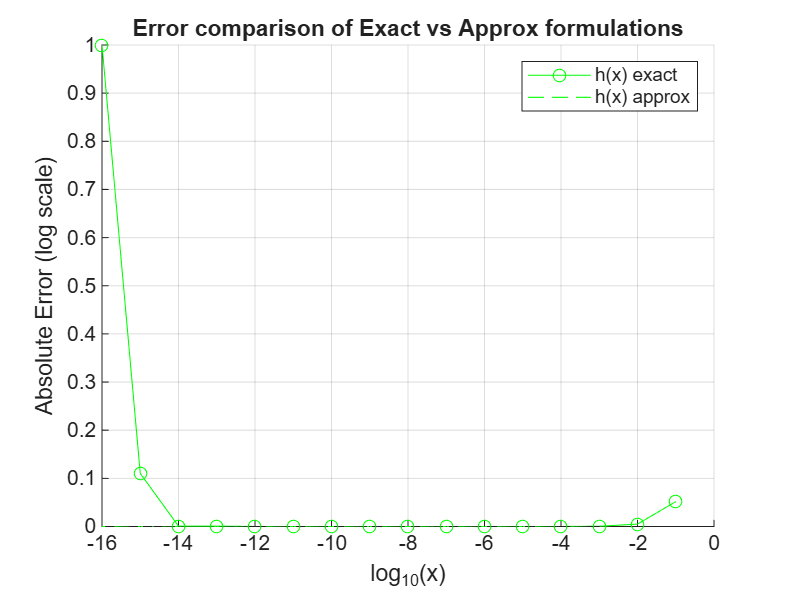

figure;
hold on;
semilogy(log10(x), err_h, 'g-o', 'DisplayName','h(x) exact');
semilogy(log10(x), err_H, 'g--', 'DisplayName','h(x) approx');
xlabel('log_{10}(x)');
ylabel('Absolute Error (log scale)');
legend show;
title('Error comparison of Exact vs Approx formulations');
grid on;

Q.3  To illustrate the immense difficulties in handling polynomials in finite precision computation

(a)

p = [1 -8 16];
fprintf("For Scalars");

For Scalars

x = 0

x = 0

fprintf("Using Horner Formula: %f", Horner(p, x));

Using Horner Formula: 16.000000

fprintf("Using Exact Formula: %f", k(x));

Using Exact Formula: 16.000000

fprintf("For Vectors");

For Vectors

x = [1, 2, 4]

x =      1     2     4


fprintf("Using Horner Formula: %f\n", Horner(p, x));

Using Horner Formula: 9.000000
Using Horner Formula: 4.000000
Using Horner Formula: 0.000000


fprintf("Using Exact Formula: %f\n", k(x));

Using Exact Formula: 9.000000
Using Exact Formula: 4.000000
Using Exact Formula: 0.000000


(b)

p = [1 -18 144 -672 2016 -4032 5376 -4608 2304 -512];
a = [1.95, 1.96, 1.97, 1.98, 1.99, 1.96];
b = [2.05, 2.04, 2.03, 2.02, 2.01, 1.99];
for i = 1 : length(a)
    x = bisect(p, a(i), b(i), 1e-8);
    fprintf("Computed Root for Root present in the interval [%f, %f] = %f\n", a(i), b(i), x);
end

Computed Root for Root present in the interval [1.950000, 2.050000] = 2.049972
Computed Root for Root present in the interval [1.960000, 2.040000] = 2.023957
Computed Root for Root present in the interval [1.970000, 2.030000] = 2.021199
Computed Root for Root present in the interval [1.980000, 2.020000] = 2.012654
Computed Root for Root present in the interval [1.990000, 2.010000] = 2.006190
Computed Root for Root present in the interval [1.960000, 1.990000] = 1.972823


(c)

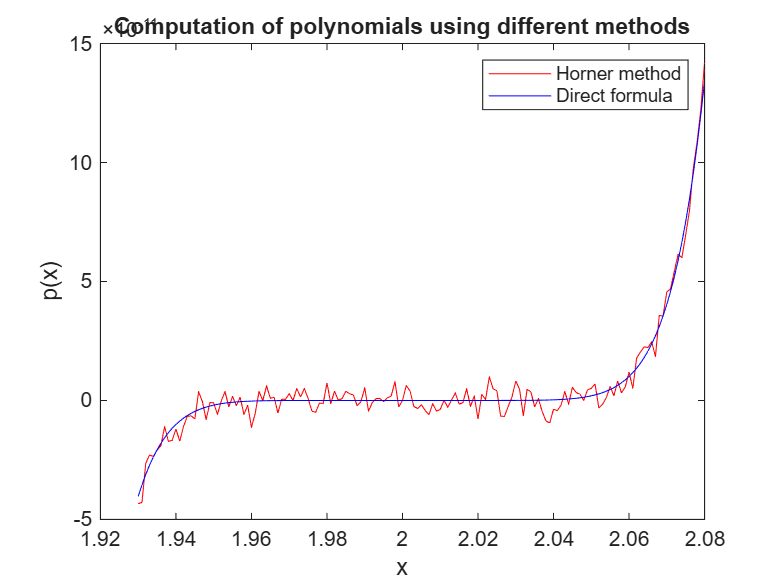

x_min = 1.93;
x_max = 2.08;
x = linspace(x_min, x_max, 151);
p = [1 -18 144 -672 2016 -4032 5376 -4608 2304 -512];
y = Horner(p, x);
Y = (x - 2) .^ 9;

plot(x, y, "red");
hold on;
plot(x, Y, "blue");
hold off;

xlabel("x");
ylabel("p(x)");
title("Computation of polynomials using different methods");
legend(["Horner method", "Direct formula"]);

**Yes**, the plots differ from one another

The plot for the **Horner method** follows a **Zic-Zag pattern** such that the curvature of the same follows that of original one.

The possible reasons for this behaviour is due to the **rounding errors** occurring while computing polynomial p(x) using **Horner's method** and the limitations of the finite precision systems.

Moreover, possibility of **Catastrophic Cancellation** occurring in **Horner's method** due to the presence of **addition** and **multiplication** at each step of computation.

### Functions

function y = Horner(p, x)
    n = length(p);
    y = zeros(size(x));
    for i = 1:n
        y = p(i) + x .* y;
    end
end

function x = bisect(p, x0, x1, tol)
    x = (x0 + x1) / 2;
    while x1 - x0 > 2 * tol
        [a, b, c] = deal(Horner(p, x0), Horner(p, x), Horner(p, x1));
        if a * b < 0
            x1 = x;
        else
            x0 = x;
        end
        x = (x0 + x1) / 2;
    end
end

function y = k(x)
    y = (x - 4) .^ 2;
end